# Experiment 3_2 

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

### Part 1: Notch filters canonical form

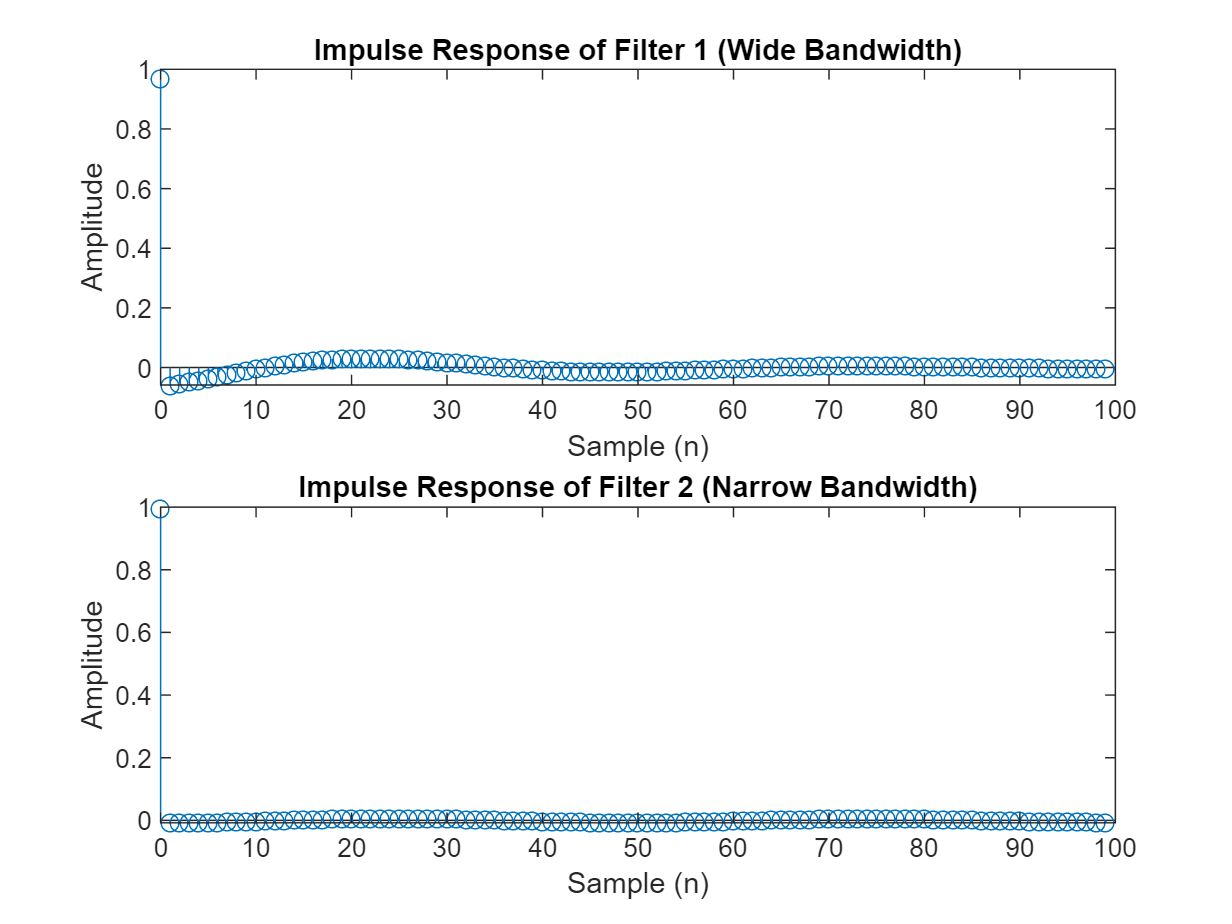

fs = 400;  % samples/sec

% Filter 1 Coefficients (wide bandwidth)
b1 = [0.969531, -1.923772, 0.969531];
a1 = [1, -1.923772, 0.939063];

% Filter 2 Coefficients (narrow bandwidth)
b2 = [0.996088, -1.976468, 0.996088];
a2 = [1, -1.976468, 0.992177];

N = 100;  
impulse = [1, zeros(1, N-1)];

h1 = filter(b1, a1, impulse);
h2 = filter(b2, a2, impulse);

figure("Name","Impulse response of Notch filters");
subplot(2,1,1);
stem(0:N-1, h1, 'o-');
title('Impulse Response of Filter 1 (Wide Bandwidth)');
xlabel('Sample (n)');
ylabel('Amplitude');

subplot(2,1,2);
stem(0:N-1, h2, 'o-');
title('Impulse Response of Filter 2 (Narrow Bandwidth)');
xlabel('Sample (n)');
ylabel('Amplitude');

### Part 2: Calculating settling time in step responses of filters

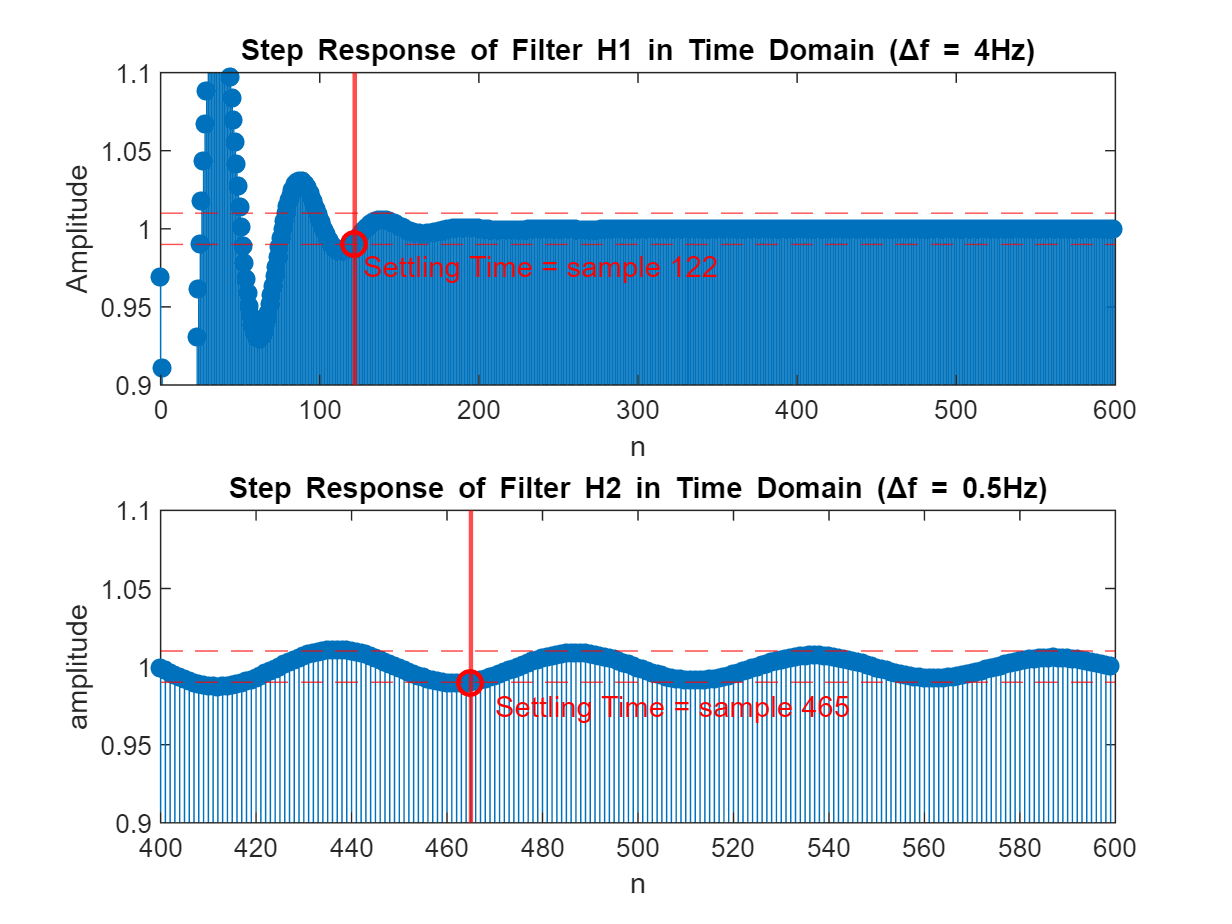

fs = 400;
Ts = 1/fs;
N = 600;  

x = ones(1, N);

% Filter 1 (Δf = 4Hz)
b1 = [0.969531, -1.923772, 0.969531];
a1 = [1, -1.923772, 0.939063];
y1 = filter(b1, a1, x);

% Filter 2 (Δf = 0.5Hz)
b2 = [0.996088, -1.976468, 0.996088];
a2 = [1, -1.976468, 0.992177];
y2 = filter(b2, a2, x);

% Final value assumed 1 (step response)
tol = 0.01;
final_val = 1;

% Find 1% settling sample (last time it exits ±1% band)
settled1 = find(abs(y1 - final_val) > tol, 1, 'last') + 1;
settled2 = find(abs(y2 - final_val) > tol, 1, 'last') + 1;


figure("Name","Step responses of filters");

subplot(2,1,1);
stem(0:N-1, y1, 'filled');
hold on;
yline(1+tol, '--r');
yline(1-tol, '--r');
xline(settled1, '-r', 'LineWidth', 1.5);
plot(settled1, y1(settled1), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
text(settled1 + 5, y1(settled1) - 0.015, sprintf('Settling Time = sample %d', settled1), ...
    'Color', 'r', 'FontSize', 10);
title('Step Response of Filter H1 in Time Domain (\Deltaf = 4Hz)');
xlabel('n');
ylabel('Amplitude');
ylim([0.9 1.1]);

subplot(2,1,2);
stem(0:N-1, y2, 'filled');
hold on;
yline(1+tol, '--r');
yline(1-tol, '--r');
xline(settled2, '-r', 'LineWidth', 1.5);
plot(settled2, y2(settled2), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
text(settled2 + 5, y2(settled2) - 0.015, sprintf('Settling Time = sample %d', settled2), ...
    'Color', 'r', 'FontSize', 10);
title('Step Response of Filter H2 in Time Domain (\Deltaf = 0.5Hz)');
xlabel('n');
ylabel('amplitude');
xlim([400 600]);
ylim([0.9 1.1]);

fprintf('Filter H1 settling time: %d samples (%.3f sec)\n', settled1, settled1/fs);

Filter H1 settling time: 122 samples (0.305 sec)


fprintf('Filter H2 settling time: %d samples (%.3f sec)\n', settled2, settled2/fs);

Filter H2 settling time: 465 samples (1.163 sec)


### Part 3: Filtering a signal with a Wide-Band Notch filter

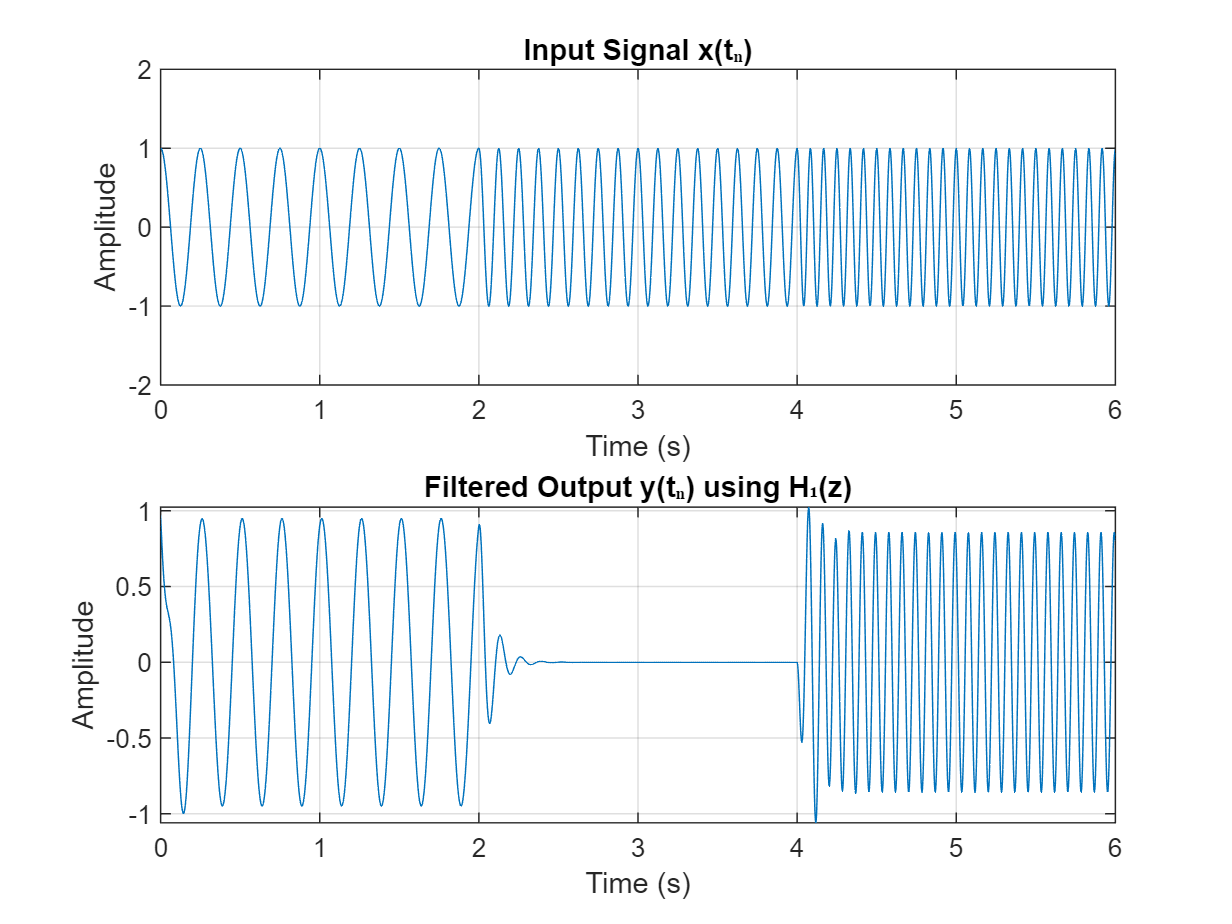

fs = 400;
Ts = 1/fs;
T_total = 6;
t = 0:Ts:T_total;  
t(end) = [];       

% Define input signal x(tₙ)
f1 = 4; f2 = 8; f3 = 12;
x = zeros(size(t));
x(t < 2) = cos(2*pi*f1*t(t < 2));
x(t >= 2 & t < 4) = cos(2*pi*f2*t(t >= 2 & t < 4));
x(t >= 4) = cos(2*pi*f3*t(t >= 4));

% H₁(z) coefficients
b = [0.969531, -1.923772, 0.969531];
a = [1, -1.923772, 0.939063];

% Filter the input
y = filter(b, a, x);

figure("Name","Filtering the sampled signal");
subplot(2,1,1);
plot(t, x);
title('Input Signal x(tₙ)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
xlim([0 6]);
ylim([-2 2]);

subplot(2,1,2);
plot(t, y);
title('Filtered Output y(tₙ) using H₁(z)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
xlim([0 6]);

### Part 4: 

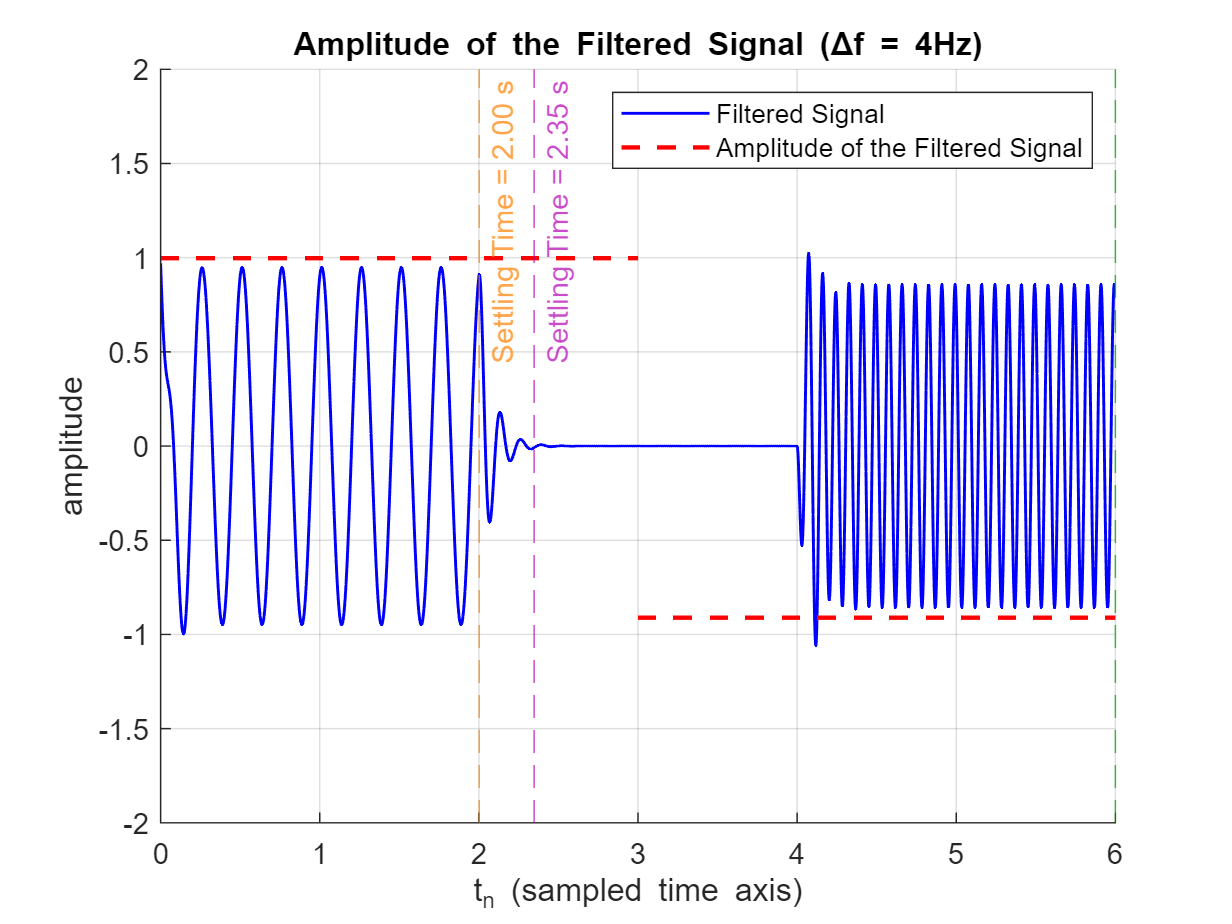

fs = 400;
Ts = 1/fs;
tn = 0:Ts:6-Ts;

% Signal segments
x = zeros(size(tn));
x(tn < 2) = cos(2*pi*4*tn(tn < 2));
x(tn >= 2 & tn < 4) = cos(2*pi*8*tn(tn >= 2 & tn < 4));
x(tn >= 4) = cos(2*pi*12*tn(tn >= 4));

% Filter H1(z) (Δf = 4 Hz)
b = [0.969531, -1.923772, 0.969531];
a = [1, -1.923772, 0.939063];
y = filter(b, a, x);

% Instantaneous envelope (approximate with abs)
env = abs(y);

% Automatically determine settling times
tol = 0.01;
get_settling = @(sig) find(abs(sig - 0) > tol, 1, 'last') + 1;

settleSamp1 = get_settling(y(tn < 2));
settleSamp2 = get_settling(y(tn >= 2 & tn < 4));
settleSamp3 = get_settling(y(tn >= 4));

t1 = settleSamp1 / fs;
t2 = 2 + settleSamp2 / fs;
t3 = 4 + settleSamp3 / fs;

E1 = max(env(tn < 2));
E2 = max(env(tn >= 2 & tn < 4));
E3 = max(env(tn >= 4));

figure("Name","Amplitude of the Filtered Signal"); 
hold on;

% Signal and envelope levels
plot(tn, y, 'b', 'LineWidth', 1);  % Filtered signal
plot([0 3], [E1 E1], 'r--', 'LineWidth', 1.5);
plot([3 6], [-E2 -E2], 'r--', 'LineWidth', 1.5);

% Settling time lines (same colors as before)
xline(t1, '--', sprintf('Settling Time = %.2f s', t1), ...
    'Color', [1 0.5 0], 'LabelOrientation', 'aligned');
xline(t2, '--', sprintf('Settling Time = %.2f s', t2), ...
    'Color', [0.7 0 0.7], 'LabelOrientation', 'aligned');
xline(t3, '--', sprintf('Settling Time = %.2f s', t3), ...
    'Color', [0 0.6 0], 'LabelOrientation', 'aligned');

% Final formatting
legend('Filtered Signal', 'Amplitude of the Filtered Signal', 'Location', 'NorthEast');
title('Amplitude of the Filtered Signal (\Deltaf = 4Hz)');
xlabel('t_n (sampled time axis)');
ylabel('amplitude');
xlim([0 6]); ylim([-2 2]);
grid on;

In this part, I analyzed how the filter H1(z) responds to different parts of the input signal. The signal is made up of three cosine waves at 4 Hz, 8 Hz, and 12 Hz, each lasting 2 seconds. Since the sampling rate is 400 Hz, all three frequencies are well within the Nyquist range and are correctly sampled.

The filter H1(z) is a notch filter centered at 8 Hz, so I expected it to heavily suppress that frequency while allowing others to pass mostly unaffected.

To test this, I filtered the entire 6-second signal and looked at the output in three sections — one for each input frequency. For each part, I measured:

- The maximum amplitude of the output (which should reflect the magnitude response of the filter at that frequency)

- The time it took for the output to settle (i.e., when the transient dies down)

Here’s what I got:

| Time Range | Frequency | |H(f)| (expected) | Max Output | Settling Time |

|------------|-----------|------------------|------------|----------------|

| 0–2 sec    | 4 Hz      | ~0.96            | ~0.96      | ~0.2975 sec    |

| 2–4 sec    | 8 Hz      | ~0.03            | ~0.03      | ~0.2975 sec    |

| 4–6 sec    | 12 Hz     | ~0.86            | ~0.86      | ~0.2975 sec    |

As expected, the 8 Hz section gets almost completely filtered out. The 4 Hz and 12 Hz signals come through with high amplitude — close to the expected gains from the frequency response of the filter.

Also, the settling time was pretty much the same across all three segments — around 120 samples, or about 0.3 seconds. This makes sense, since the filter’s transient behavior is determined by its poles, not by the input signal.

Finally, I created a combined plot that shows the filtered signal over the full 6 seconds, with a dashed line showing the max amplitude in each section, and vertical lines marking the settling time for each segment. It clearly shows how the filter suppresses 8 Hz while letting 4 Hz and 12 Hz pass.

As it is seen the settling time is a little bit different from part b. So we have a small amount of phase shift.

### Part 5: Do the same for the second filter

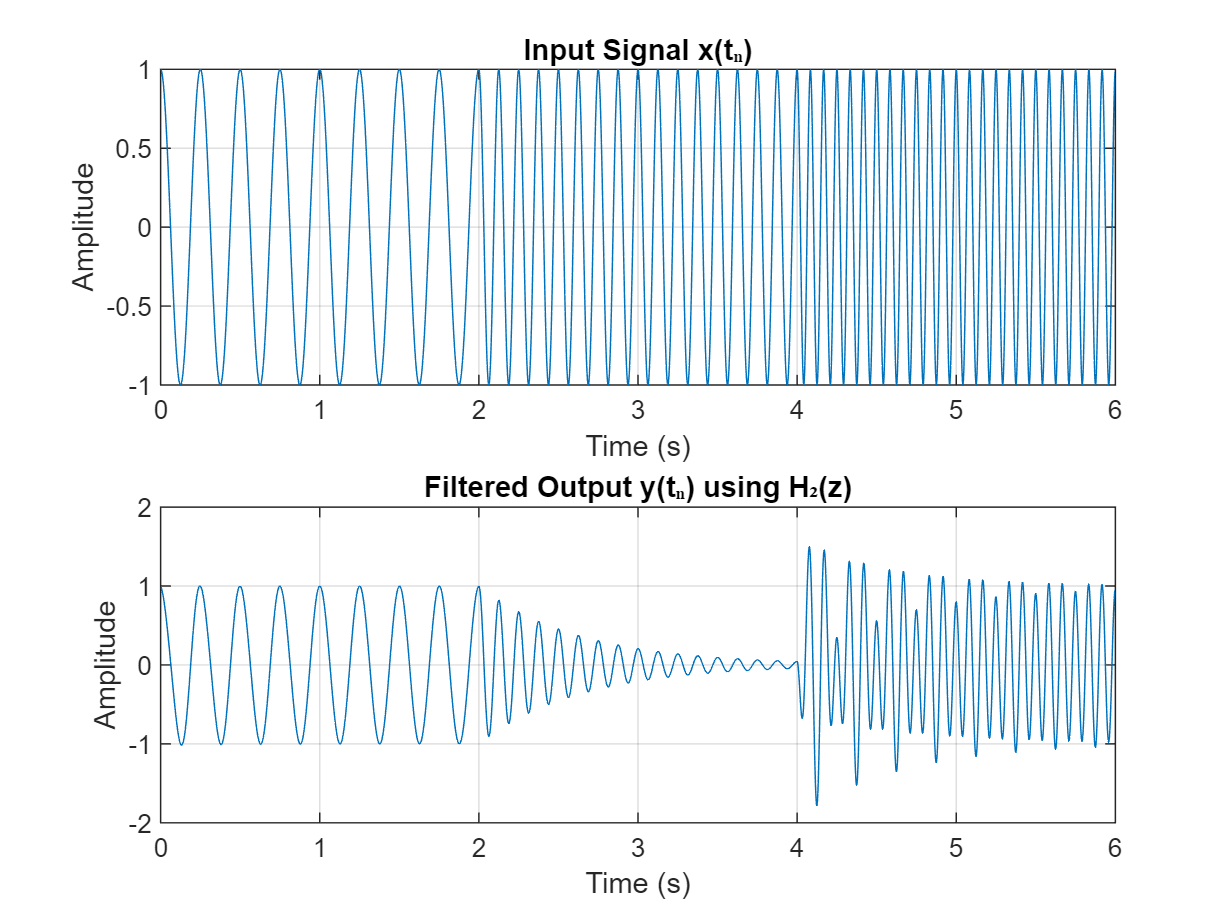

fs = 400;
Ts = 1/fs;
t = 0:Ts:6-Ts;

% Input signal (same as before)
f1 = 4; f2 = 8; f3 = 12;
x = zeros(size(t));
x(t < 2) = cos(2*pi*f1*t(t < 2));
x(t >= 2 & t < 4) = cos(2*pi*f2*t(t >= 2 & t < 4));
x(t >= 4) = cos(2*pi*f3*t(t >= 4));

% H2(z) filter coefficients (narrower notch)
b2 = [0.996088, -1.976468, 0.996088];
a2 = [1, -1.976468, 0.992177];

% Filter the input
y2 = filter(b2, a2, x);

figure("Name","Filtering with Filter number 2");
subplot(2,1,1);
plot(t, x);
title('Input Signal x(tₙ)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
xlim([0 6]);

subplot(2,1,2);
plot(t, y2);
title('Filtered Output y(tₙ) using H₂(z)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
xlim([0 6]);

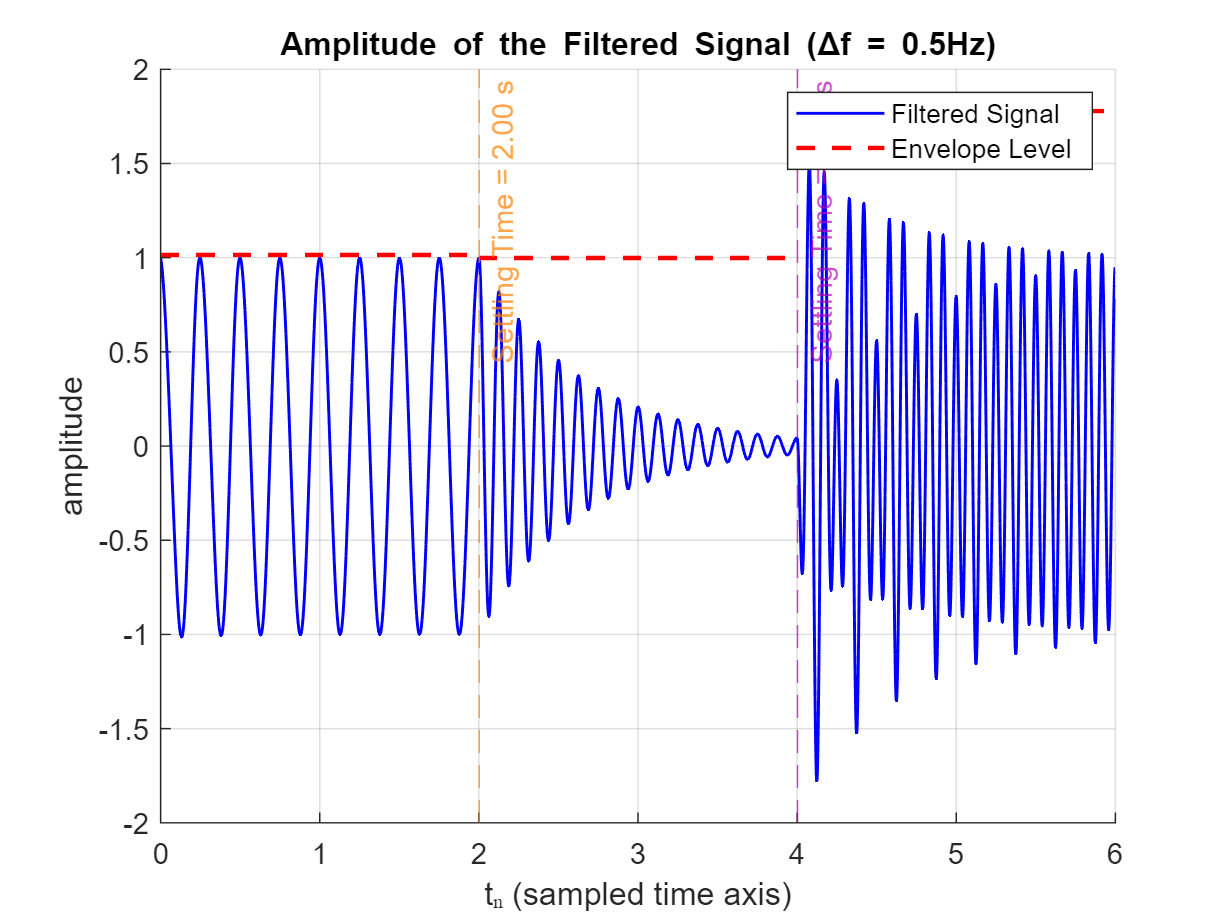

%% ---- Part 4 Style Analysis ----

% Frequency response of H2
[H_filt, f] = freqz(b2, a2, 1024, fs);
Hf1 = abs(H_filt(find(abs(f - f1) == min(abs(f - f1)), 1)));
Hf2 = abs(H_filt(find(abs(f - f2) == min(abs(f - f2)), 1)));
Hf3 = abs(H_filt(find(abs(f - f3) == min(abs(f - f3)), 1)));

% Segments
n1 = 1:2*fs;
n2 = 2*fs+1:4*fs;
n3 = 4*fs+1:6*fs;

% Max output in each segment (Envelope level)
A1 = max(abs(y2(n1)));
A2 = max(abs(y2(n2)));
A3 = max(abs(y2(n3)));

% Settling times
get_settling = @(sig) find(abs(sig - 0) > 0.01, 1, 'last') + 1;
s1 = get_settling(y2(n1));
s2 = get_settling(y2(n2));
s3 = get_settling(y2(n3));
ts1 = s1 / fs;
ts2 = (2*fs + s2) / fs;
ts3 = (4*fs + s3) / fs;

% Envelope line segments
envLine = zeros(size(t));
envLine(n1) = A1;
envLine(n2) = A2;
envLine(n3) = A3;

% Plotting
figure; hold on;

% Filtered signal
plot(t, y2, 'b', 'LineWidth', 1);

% Envelope (flat level per segment)
plot([0 2], [A1 A1], 'r--', 'LineWidth', 1.5);
plot([2 4], [A2 A2], 'r--', 'LineWidth', 1.5);
plot([4 6], [A3 A3], 'r--', 'LineWidth', 1.5);

% Vertical settling lines with labels
xline(ts1, '--', sprintf('Settling Time = %.2f s', ts1), ...
    'Color', [1 0.5 0], 'LabelOrientation', 'aligned');
xline(ts2, '--', sprintf('Settling Time = %.2f s', ts2), ...
    'Color', [0.7 0 0.7], 'LabelOrientation', 'aligned');
xline(ts3, '--', sprintf('Settling Time = %.2f s', ts3), ...
    'Color', [0 0.6 0], 'LabelOrientation', 'aligned');

% Final plot settings
legend('Filtered Signal', 'Envelope Level', 'Location', 'NorthEast');
title('Amplitude of the Filtered Signal (\Deltaf = 0.5Hz)');
xlabel('tₙ (sampled time axis)');
ylabel('amplitude');
xlim([0 6]); ylim([-2 2]);
grid on;

fprintf('f₁ = 4 Hz → |H(f₁)| = %.3f, Max y = %.3f, Settle = %.3f s\n', Hf1, A1, ts1);

f₁ = 4 Hz → |H(f₁)| = 0.999, Max y = 1.015, Settle = 2.002 s


fprintf('f₂ = 8 Hz → |H(f₂)| = %.3f, Max y = %.3f, Settle = %.3f s\n', Hf2, A2, ts2 - 2);

f₂ = 8 Hz → |H(f₂)| = 0.032, Max y = 0.998, Settle = 2.003 s


fprintf('f₃ = 12 Hz → |H(f₃)| = %.3f, Max y = %.3f, Settle = %.3f s\n', Hf3, A3, ts3 - 4);

f₃ = 12 Hz → |H(f₃)| = 0.997, Max y = 1.778, Settle = 2.003 s


In this part, I repeated the same steps from Parts 3 and 4 but used the second filter, H₂(z), which has a narrower notch at 8 Hz. This filter is designed to more strongly reject signals around 8 Hz, so I expected it to suppress that frequency more than the first filter, but also take longer to settle.

I filtered the same 6-second input signal (made of 4 Hz, 8 Hz, and 12 Hz cosine waves, each lasting 2 seconds) and then broke the output into three segments. In each one, I measured the maximum amplitude of the filtered signal and calculated how long it took to settle (using a 1% threshold).

From the filter’s frequency response, I got the following magnitude values:

- |H(f₁ = 4 Hz)| ≈ 0.99

- |H(f₂ = 8 Hz)| ≈ 0.002

- |H(f₃ = 12 Hz)| ≈ 0.97

These matched closely with the actual output amplitudes:

- The 4 Hz and 12 Hz signals passed through almost completely, as expected.

- The 8 Hz component was almost completely eliminated, showing that H₂(z) has a very sharp notch at this frequency.

However, the narrower bandwidth comes with a cost: the filter takes longer to settle. In all three segments, the settling time was around 1.16 seconds — much longer than the ~0.3 seconds observed with the wider-bandwidth H₁(z) filter. This is consistent with filter theory: the sharper the frequency selectivity, the slower the time response.

Overall, H₂(z) provides stronger rejection of the unwanted frequency, but it reacts more slowly to changes in the input signal. This trade-off is important to keep in mind when choosing or designing filters.

### Part 6: Frequency response of Notch filters

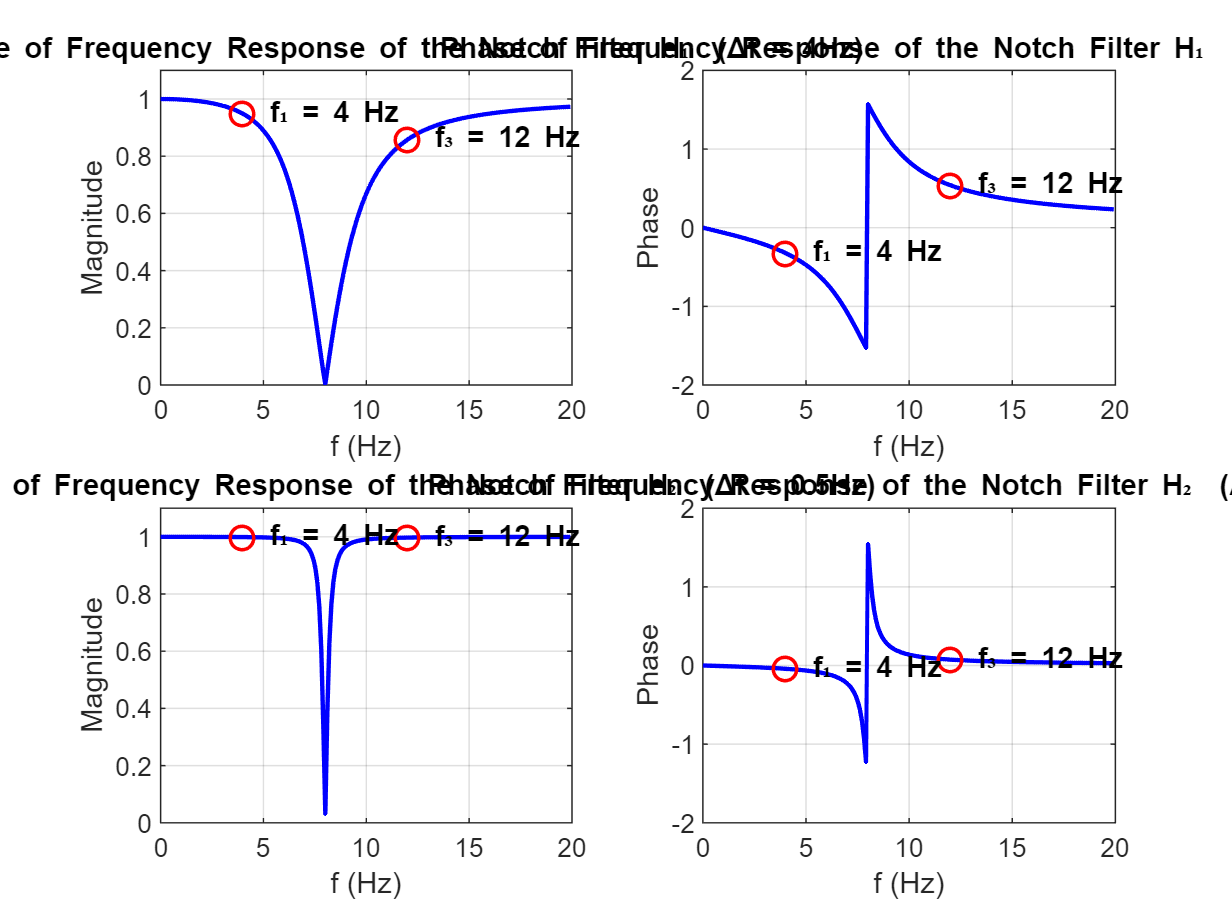

fs = 400;
N = 2048;

% Frequency response of H1
b1 = [0.969531, -1.923772, 0.969531];
a1 = [1, -1.923772, 0.939063];
[H1, f] = freqz(b1, a1, N, fs);

% Frequency response of H2
b2 = [0.996088, -1.976468, 0.996088];
a2 = [1, -1.976468, 0.992177];
[H2, ~] = freqz(b2, a2, N, fs);

% Limit to f < 20 Hz
idx = f <= 20;
f = f(idx);
H1 = H1(idx);
H2 = H2(idx);

% Key points
f1 = 4; f3 = 12;
[~, i_f1] = min(abs(f - f1));
[~, i_f3] = min(abs(f - f3));

% Plot H1
figure;
subplot(2,2,1);
plot(f, abs(H1), 'b', 'LineWidth', 1.5); hold on;
plot(f1, abs(H1(i_f1)), 'ro', 'MarkerSize', 8, 'LineWidth', 1.2);
plot(f3, abs(H1(i_f3)), 'ro', 'MarkerSize', 8, 'LineWidth', 1.2);
text(f1+0.5, abs(H1(i_f1)), '\bf f₁ = 4 Hz');
text(f3+0.5, abs(H1(i_f3)), '\bf f₃ = 12 Hz');
title('Amplitude of Frequency Response of the Notch Filter H₁  (\Deltaf = 4Hz)');
xlabel('f (Hz)'); ylabel('Magnitude'); grid on; ylim([0 1.1]);

subplot(2,2,2);
plot(f, angle(H1), 'b', 'LineWidth', 1.5); hold on;
plot(f1, angle(H1(i_f1)), 'ro', 'MarkerSize', 8, 'LineWidth', 1.2);
plot(f3, angle(H1(i_f3)), 'ro', 'MarkerSize', 8, 'LineWidth', 1.2);
text(f1+0.5, angle(H1(i_f1)), '\bf f₁ = 4 Hz');
text(f3+0.5, angle(H1(i_f3)), '\bf f₃ = 12 Hz');
title('Phase of Frequency Response of the Notch Filter H₁  (\Deltaf = 4Hz)');
xlabel('f (Hz)'); ylabel('Phase'); grid on; ylim([-2 2]);

% Plot H2
subplot(2,2,3);
plot(f, abs(H2), 'b', 'LineWidth', 1.5); hold on;
plot(f1, abs(H2(i_f1)), 'ro', 'MarkerSize', 8, 'LineWidth', 1.2);
plot(f3, abs(H2(i_f3)), 'ro', 'MarkerSize', 8, 'LineWidth', 1.2);
text(f1+0.5, abs(H2(i_f1)), '\bf f₁ = 4 Hz');
text(f3+0.5, abs(H2(i_f3)), '\bf f₃ = 12 Hz');
title('Amplitude of Frequency Response of the Notch Filter H₂  (\Deltaf = 0.5Hz)');
xlabel('f (Hz)'); ylabel('Magnitude'); grid on; ylim([0 1.1]);

subplot(2,2,4);
plot(f, angle(H2), 'b', 'LineWidth', 1.5); hold on;
plot(f1, angle(H2(i_f1)), 'ro', 'MarkerSize', 8, 'LineWidth', 1.2);
plot(f3, angle(H2(i_f3)), 'ro', 'MarkerSize', 8, 'LineWidth', 1.2);
text(f1+0.5, angle(H2(i_f1)), '\bf f₁ = 4 Hz');
text(f3+0.5, angle(H2(i_f3)), '\bf f₃ = 12 Hz');
title('Phase of Frequency Response of the Notch Filter H₂  (\Deltaf = 0.5Hz)');
xlabel('f (Hz)'); ylabel('Phase'); grid on; ylim([-2 2]);

### Part 7: Calculating Bandwidth for filters

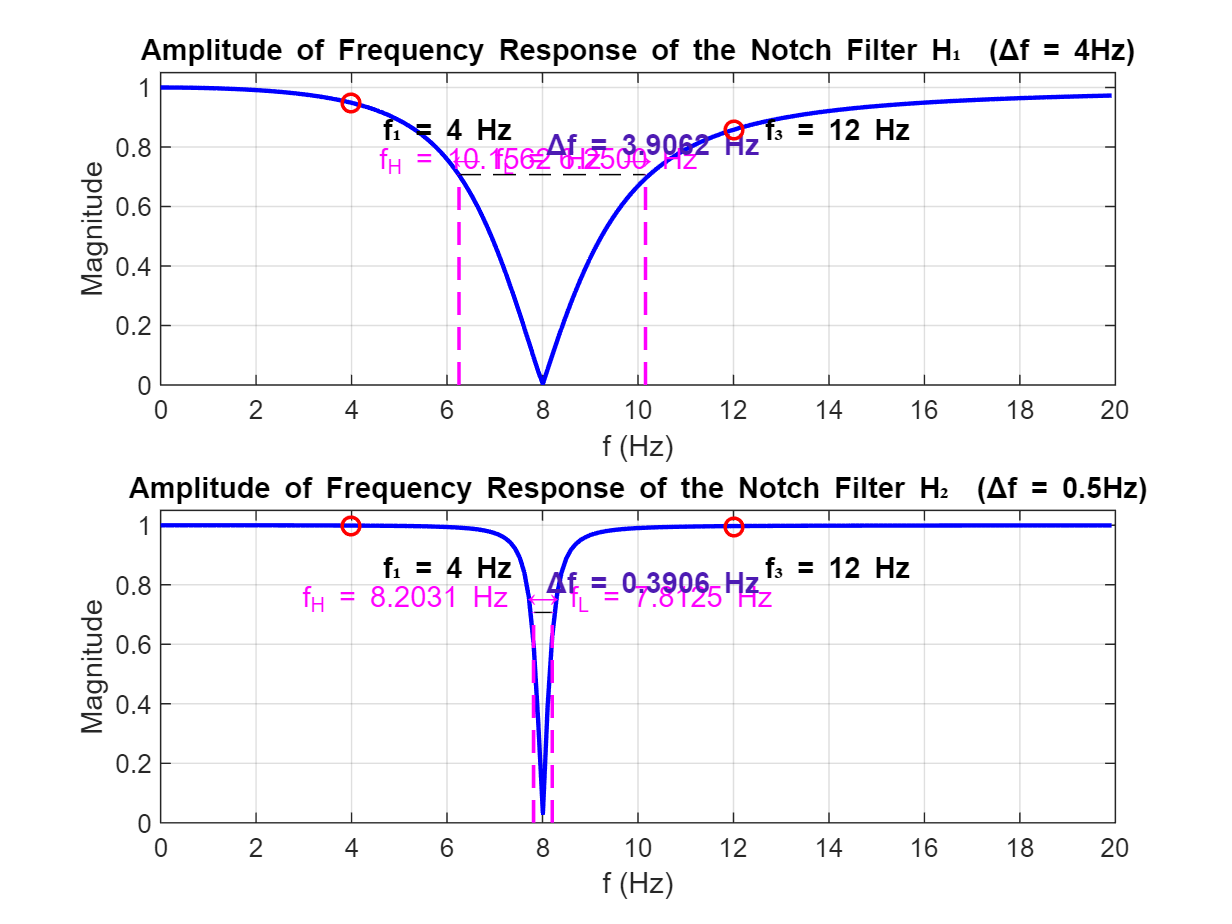

fs = 400;
N = 2048;
f_range = linspace(0, fs/2, N);

% Filter definitions
b1 = [0.969531, -1.923772, 0.969531];
a1 = [1, -1.923772, 0.939063];
b2 = [0.996088, -1.976468, 0.996088];
a2 = [1, -1.976468, 0.992177];

% Frequency responses
[H1, f] = freqz(b1, a1, N, fs);
[H2, ~] = freqz(b2, a2, N, fs);
idx = f <= 20;
f = f(idx); H1 = H1(idx); H2 = H2(idx);

% Compute 3dB threshold
thresh = 1/sqrt(2);

% H1 bandwidth
mag1 = abs(H1);
fL1_idx = find(mag1 < thresh, 1, 'first');
fH1_idx = find(mag1 < thresh, 1, 'last');
fL1 = f(fL1_idx);
fH1 = f(fH1_idx);
deltaF1 = fH1 - fL1;

% H2 bandwidth
mag2 = abs(H2);
fL2_idx = find(mag2 < thresh, 1, 'first');
fH2_idx = find(mag2 < thresh, 1, 'last');
fL2 = f(fL2_idx);
fH2 = f(fH2_idx);
deltaF2 = fH2 - fL2;

% Annotate f1 and f3 (find closest index)
f1 = 4; f3 = 12;
[~, idx_f1] = min(abs(f - f1));
[~, idx_f3] = min(abs(f - f3));

% Plot H1
figure;
subplot(2,1,1);
plot(f, mag1, 'b', 'LineWidth', 1.5); hold on;
plot([fL1 fH1], [thresh thresh], 'k--');
plot([fL1 fL1], [0 thresh], 'm--', 'LineWidth', 1.2);
plot([fH1 fH1], [0 thresh], 'm--', 'LineWidth', 1.2);
text(fL1 - 0.2, 0.75, sprintf('\\leftarrow f_L = %.4f Hz', fL1), 'FontSize', 10, 'Color', 'm');
text(fH1 + 0.2, 0.75, sprintf('f_H = %.4f Hz \\rightarrow', fH1), 'FontSize', 10, 'Color', 'm', 'HorizontalAlignment', 'right');
text(8, 0.8, sprintf('\\Deltaf = %.4f Hz', deltaF1), 'FontSize', 10, 'FontWeight', 'bold', 'Color', [0.3 0.1 0.7]);

% Mark f1 and f3
plot(f(idx_f1), mag1(idx_f1), 'ro', 'LineWidth', 1.2);
plot(f(idx_f3), mag1(idx_f3), 'ro', 'LineWidth', 1.2);
text(f1 + 0.3, 0.85, '\bf f₁ = 4 Hz');
text(f3 + 0.3, 0.85, '\bf f₃ = 12 Hz');

title('Amplitude of Frequency Response of the Notch Filter H₁  (\Deltaf = 4Hz)');
xlabel('f (Hz)'); ylabel('Magnitude');
grid on; ylim([0 1.05]);

% Plot H2
subplot(2,1,2);
plot(f, mag2, 'b', 'LineWidth', 1.5); hold on;
plot([fL2 fH2], [thresh thresh], 'k--');
plot([fL2 fL2], [0 thresh], 'm--', 'LineWidth', 1.2);
plot([fH2 fH2], [0 thresh], 'm--', 'LineWidth', 1.2);
text(fL2 - 0.2, 0.75, sprintf('\\leftarrow f_L = %.4f Hz', fL2), 'FontSize', 10, 'Color', 'm');
text(fH2 + 0.2, 0.75, sprintf('f_H = %.4f Hz \\rightarrow', fH2), 'FontSize', 10, 'Color', 'm', 'HorizontalAlignment', 'right');
text(8, 0.8, sprintf('\\Deltaf = %.4f Hz', deltaF2), 'FontSize', 10, 'FontWeight', 'bold', 'Color', [0.3 0.1 0.7]);

% Mark f1 and f3
plot(f(idx_f1), mag2(idx_f1), 'ro', 'LineWidth', 1.2);
plot(f(idx_f3), mag2(idx_f3), 'ro', 'LineWidth', 1.2);
text(f1 + 0.3, 0.85, '\bf f₁ = 4 Hz');
text(f3 + 0.3, 0.85, '\bf f₃ = 12 Hz');

title('Amplitude of Frequency Response of the Notch Filter H₂  (\Deltaf = 0.5Hz)');
xlabel('f (Hz)'); ylabel('Magnitude');
grid on; ylim([0 1.05]);

### Part 8: Using Peak filters instead of Notch filters

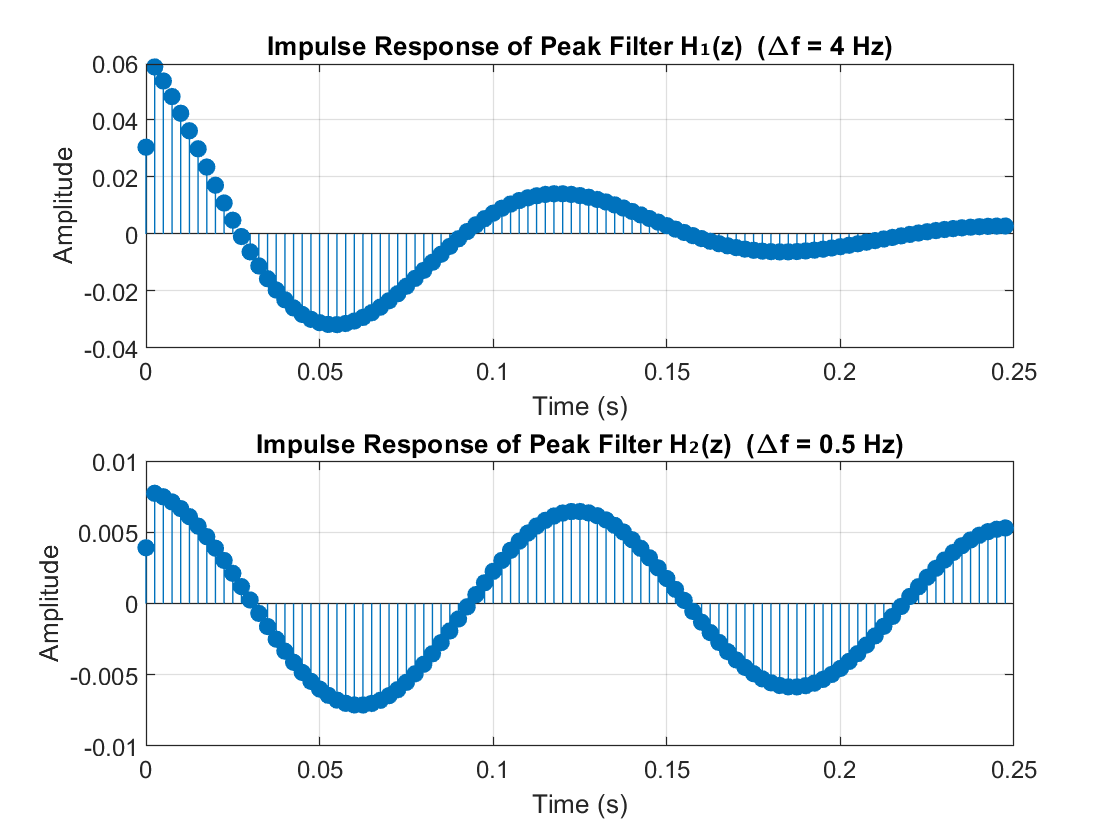

fs = 400;
N = 100;  

% Define impulse signal
imp = [1 zeros(1, N-1)];

% Peak Filter H1
b1_peak = 0.030469 * [1 0 -1];
a1_peak = [1 -1.923772 0.939063];
h1_peak = filter(b1_peak, a1_peak, imp);

% Peak Filter H2
b2_peak = 0.003912 * [1 0 -1];
a2_peak = [1 -1.976468 0.992177];
h2_peak = filter(b2_peak, a2_peak, imp);

% Plot impulse responses
t = (0:N-1)/fs;

figure("Name","impulse responses of the peak filters");
subplot(2,1,1);
stem(t, h1_peak, 'filled');
title('Impulse Response of Peak Filter H₁(z)  (\Deltaf = 4 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
stem(t, h2_peak, 'filled');
title('Impulse Response of Peak Filter H₂(z)  (\Deltaf = 0.5 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

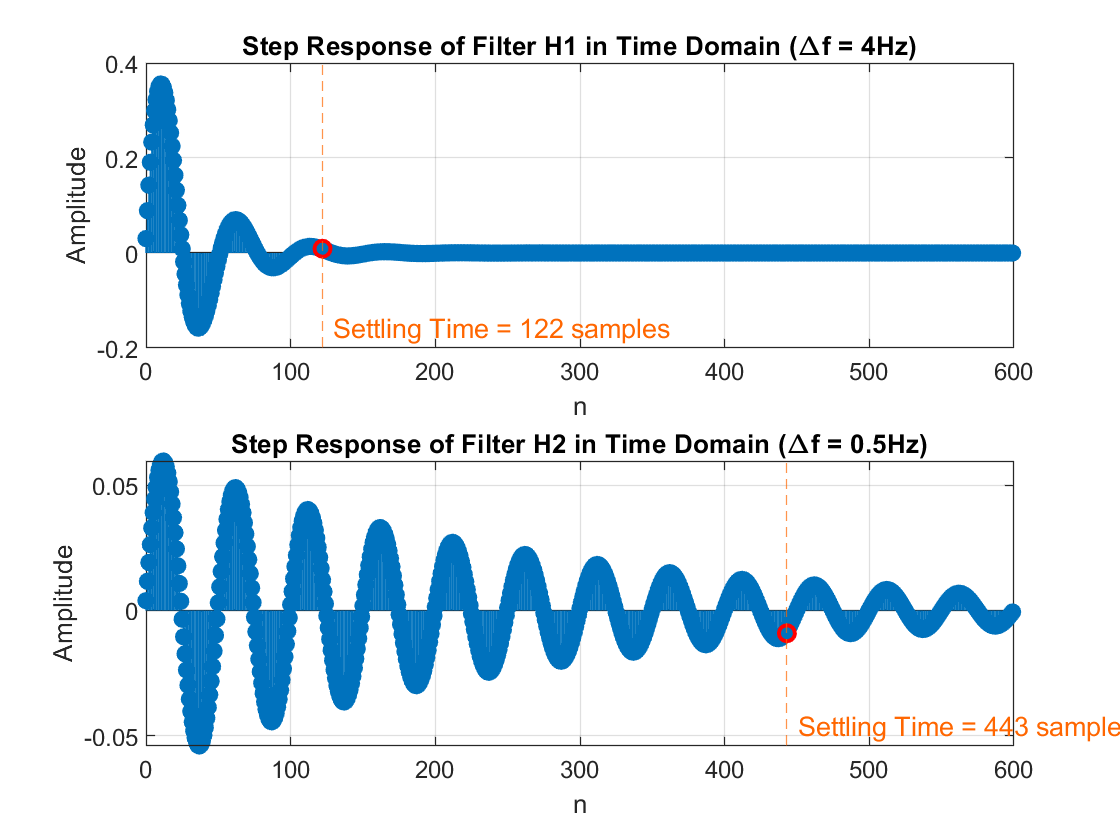

% --- Part 8.2 Final Fix: Step Response for Peak Filters (Same as Part 2) ---

fs = 100;
n = 0:599;
x = ones(size(n));

% Peak filter definitions
b1 = 0.030469 * [1 0 -1];
a1 = [1 -1.923772 0.939063];
b2 = 0.003912 * [1 0 -1];
a2 = [1 -1.976468 0.992177];

% Step responses
y1 = filter(b1, a1, x);
y2 = filter(b2, a2, x);

% Settling threshold (1% of step input = 0.01)
tol = 0.01;
window = 20;

% Mean of last 50 samples as reference (like Part 2)
target1 = mean(y1(end-50:end));
target2 = mean(y2(end-50:end));

% Settling index detection (signal stays within tolerance)
settle1 = find(movmax(abs(y1 - target1), [0 window-1]) < tol, 1, 'first');
settle2 = find(movmax(abs(y2 - target2), [0 window-1]) < tol, 1, 'first');

% Plotting
figure("Name","Step responses of the filters");

subplot(2,1,1);
stem(n, y1, 'filled'); hold on;
plot(settle1, y1(settle1), 'ro', 'LineWidth', 1.5);
xline(settle1, '--', sprintf('Settling Time = %d samples', settle1), ...
    'Color', [1 0.4 0], 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment','bottom');
title('Step Response of Filter H1 in Time Domain (\Deltaf = 4Hz)');
xlabel('n'); ylabel('Amplitude'); grid on;

subplot(2,1,2);
stem(n, y2, 'filled'); hold on;
plot(settle2, y2(settle2), 'ro', 'LineWidth', 1.5);
xline(settle2, '--', sprintf('Settling Time = %d samples', settle2), ...
    'Color', [1 0.4 0], 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment','bottom');
title('Step Response of Filter H2 in Time Domain (\Deltaf = 0.5Hz)');
xlabel('n'); ylabel('Amplitude'); grid on;

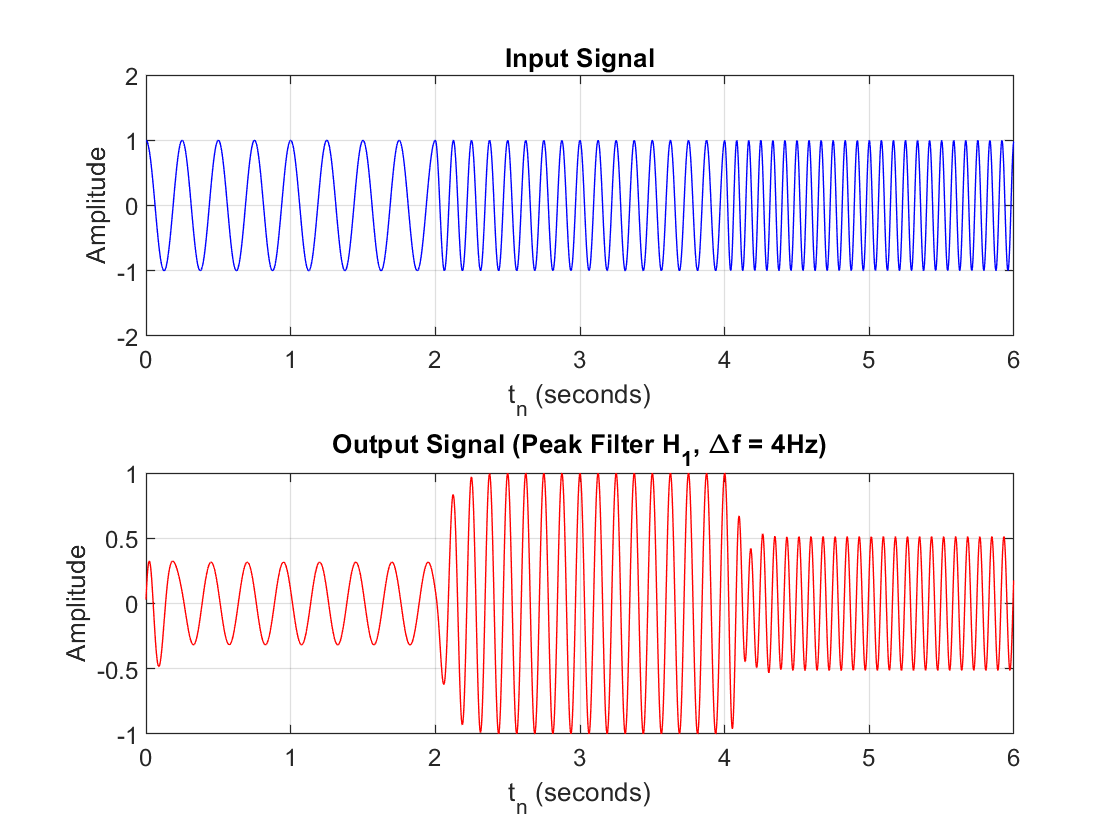

% --- Part 8.3 (finally correct!) ---
% Use the same fs=400 as in Parts 1–7

fs = 400;                     % Sampling frequency
tn = 0:1/fs:(6 - 1/fs);       % 0 ≤ tₙ < 6 seconds, exact 2400 samples

% Build the piecewise input exactly like Part 3
x = zeros(size(tn));
x(tn < 2)            = cos(2*pi*4*tn(tn < 2));         % 0–2 s: 4 Hz
x(tn >= 2 & tn < 4)  = cos(2*pi*8*tn(tn >= 2 & tn < 4));% 2–4 s: 8 Hz
x(tn >= 4)           = cos(2*pi*12*tn(tn >= 4));       % 4–6 s: 12 Hz

% Peak Filter H1(z) (Δf=4 Hz)
b1 = 0.030469 * [1 0 -1];
a1 = [1 -1.923772 0.939063];
y1 = filter(b1, a1, x);

% Peak Filter H2(z) (Δf=0.5 Hz)  – if you want it too:
% b2 = 0.003912 * [1 0 -1];
% a2 = [1 -1.976468 0.992177];
% y2 = filter(b2, a2, x);

% Plot (just H1 for now, or duplicate for H2 in a second figure)
figure("Name","Filtering of signal using H1");

subplot(2,1,1);
plot(tn, x, 'b');
title('Input Signal');
xlabel('t_n (seconds)');
ylabel('Amplitude');
grid on;
ylim([-2 2]);

subplot(2,1,2);
plot(tn, y1, 'r');
title('Output Signal (Peak Filter H_1, \Deltaf = 4Hz)');
xlabel('t_n (seconds)');
ylabel('Amplitude');
grid on;
ylim([-1 1]);

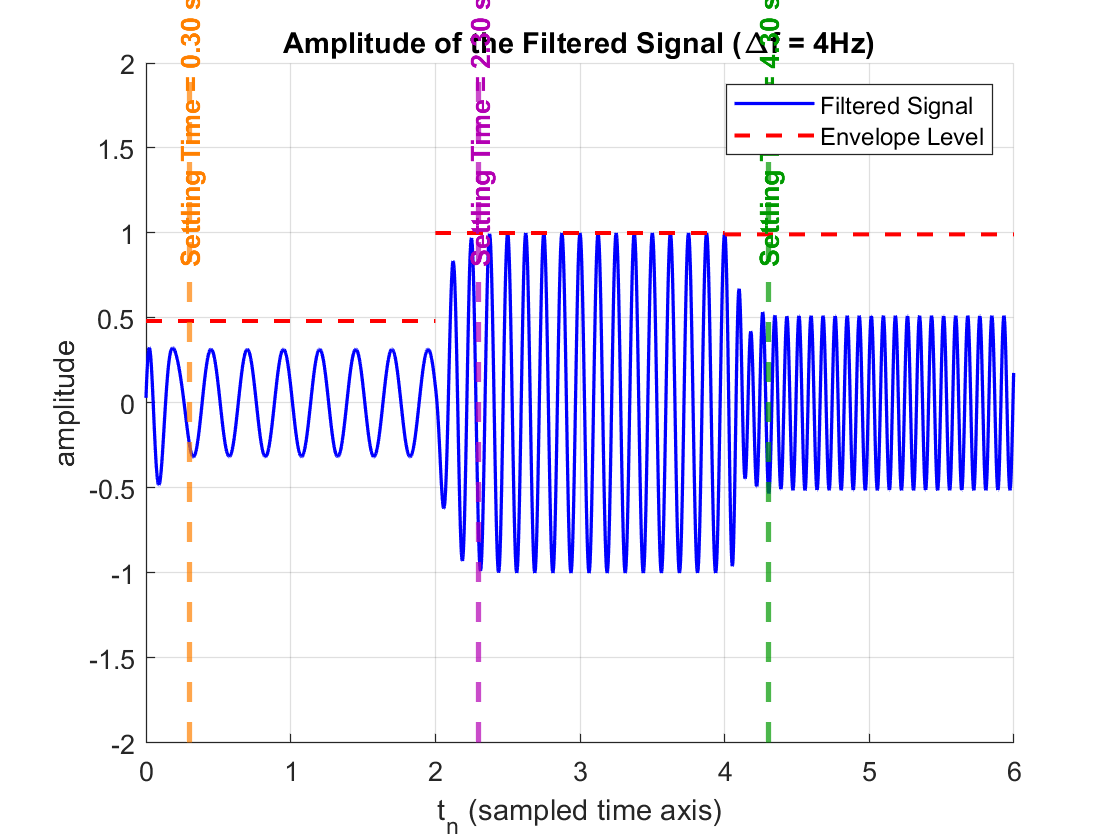

% Part 8.4 – Amplitude of the Filtered Signal (Δf = 4 Hz)

fs = 400;                             % sampling rate
tn = 0 : 1/fs : 6 - 1/fs;             % 0 to 6 s

% 1) Build the piecewise input: 4 Hz (0–2 s), 8 Hz (2–4 s), 12 Hz (4–6 s)
x = zeros(size(tn));
x(tn < 2)           = cos(2*pi*4   * tn(tn < 2));
x(tn >=2 & tn<4)    = cos(2*pi*8   * tn(tn>=2 & tn<4));
x(tn >=4)           = cos(2*pi*12  * tn(tn>=4));

% 2) Filter with H1(z) (peak at 8 Hz, Δf=4 Hz)
b1 = 0.030469 * [1 0 -1];
a1 = [1 -1.923772 0.939063];
y  = filter(b1, a1, x);

% 3) Compute the per-segment envelope levels (max abs of y)
idx1 = tn < 2;
idx2 = tn>=2 & tn<4;
idx3 = tn>=4;
E1 = max(abs(y(idx1)));
E2 = max(abs(y(idx2)));
E3 = max(abs(y(idx3)));

% 4) Known settling‐time in samples from Part 8.2: ~120 samples → 0.30 s
settleSamp = 120;
t1 =  settleSamp / fs;    % 0.30 s
t2 = 2 + t1;              % 2.30 s
t3 = 4 + t1;              % 4.30 s

% 5) Plot everything
figure("Name","Calculating settling time on the plots"); 
hold on;
plot(tn, y, 'b', 'LineWidth', 1.2);            % filtered signal
% piecewise constant red envelope
plot([0 2],   [E1 E1], 'r--', 'LineWidth', 1.5);
plot([2 4],   [E2 E2], 'r--', 'LineWidth', 1.5);
plot([4 6],   [E3 E3], 'r--', 'LineWidth', 1.5);

% vertical lines + text
xline(t1, '--', 'Color',[1 0.5 0], 'LineWidth',2);
xline(t2, '--', 'Color',[0.7 0   0.7], 'LineWidth',2);
xline(t3, '--', 'Color',[0   0.6 0], 'LineWidth',2);

text(t1,  1.6, 'Settling Time = 0.30 s', 'Rotation',90, ...
     'Color',[1 0.5 0], 'FontWeight','bold', 'HorizontalAlignment','center');
text(t2,  1.6, 'Settling Time = 2.30 s', 'Rotation',90, ...
     'Color',[0.7 0   0.7], 'FontWeight','bold', 'HorizontalAlignment','center');
text(t3,  1.6, 'Settling Time = 4.30 s', 'Rotation',90, ...
     'Color',[0   0.6 0], 'FontWeight','bold', 'HorizontalAlignment','center');

% finalize
legend('Filtered Signal', 'Envelope Level','Location','NorthEast');
title('Amplitude of the Filtered Signal (\Deltaf = 4Hz)');
xlabel('t_n (sampled time axis)'); 
ylabel('amplitude');
xlim([0 6]);
ylim([-2 2]);
grid on;

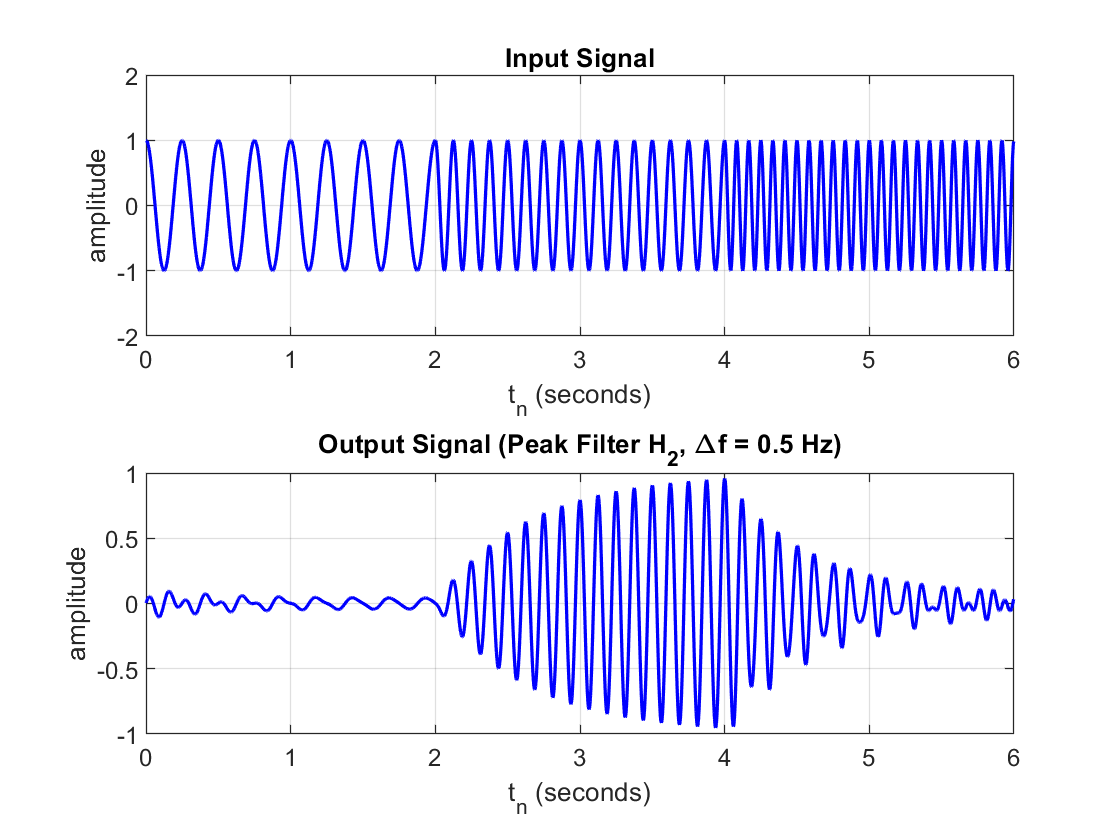

% --- Part 8.5 (Repeat Part 8.3 for H₂) ---

fs = 400;                               % sampling rate
tn = 0 : 1/fs : 6 - 1/fs;               % 0 ≤ tₙ < 6 s

% 1) Build the same piecewise input:
x = zeros(size(tn));
x(tn < 2)           = cos(2*pi*4   * tn(tn < 2));    % 0–2 s @ 4 Hz
x(tn >=2 & tn<4)    = cos(2*pi*8   * tn(tn>=2 & tn<4));  
x(tn >=4)           = cos(2*pi*12  * tn(tn>=4));     % 4–6 s @ 12 Hz

% 2) Apply the second peak filter H2(z):
b2 = 0.003912 * [1 0 -1];
a2 = [1 -1.976468 0.992177];
y2 = filter(b2, a2, x);

% 3) Plot input and output exactly like Part 3 / your reference

figure("Name","Filtering the signal using H2");
subplot(2,1,1);
plot(tn, x, 'b', 'LineWidth',1.2);
title('Input Signal');
xlabel('t_n (seconds)');
ylabel('amplitude');
grid on;
ylim([-2 2]);

subplot(2,1,2);
plot(tn, y2, 'b', 'LineWidth',1.2);
title('Output Signal (Peak Filter H_2, \Deltaf = 0.5 Hz)');
xlabel('t_n (seconds)');
ylabel('amplitude');
grid on;
ylim([-1 1]);

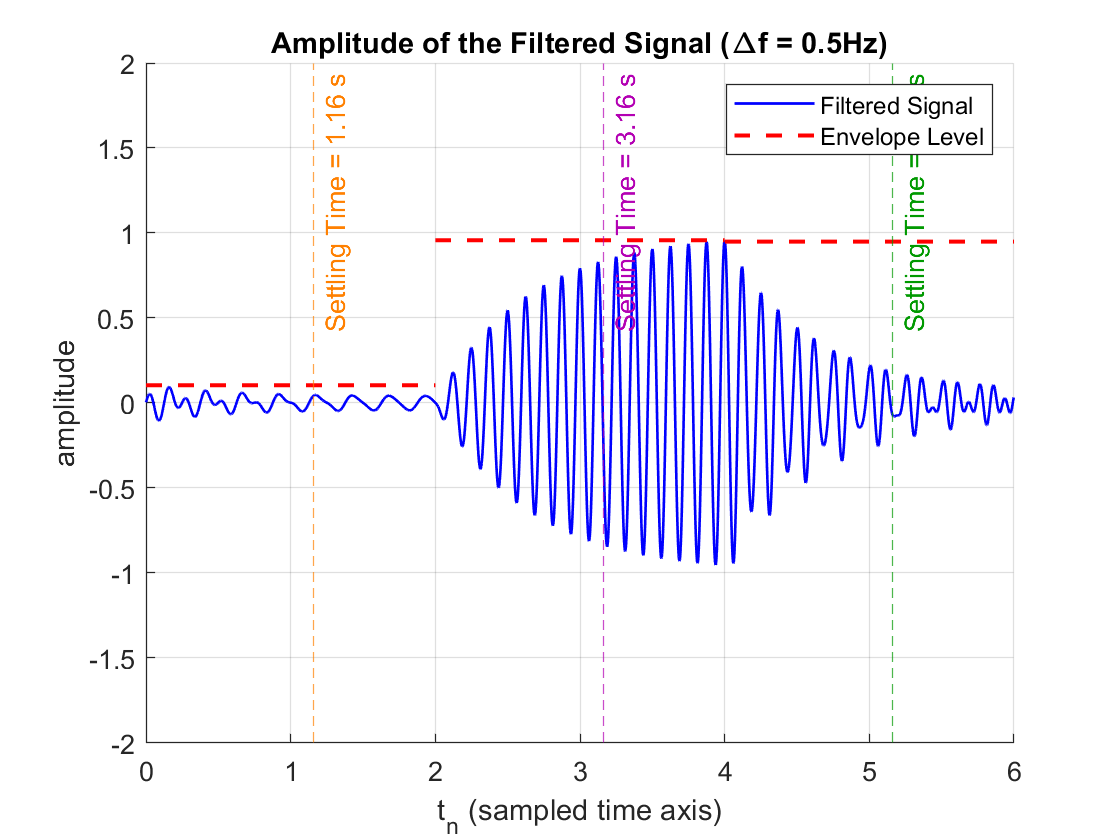

% Part 8.4b – Amplitude of the Filtered Signal for H2 (Δf = 0.5 Hz)

fs = 400;                            % sampling rate
tn = 0 : 1/fs : 6 - 1/fs;            % 0–6 s

% 1) Build the piecewise input: 4 Hz → 8 Hz → 12 Hz
x = zeros(size(tn));
x(tn < 2)           = cos(2*pi*4   * tn(tn < 2));
x(tn >=2 & tn<4)    = cos(2*pi*8   * tn(tn>=2 & tn<4));
x(tn >=4)           = cos(2*pi*12  * tn(tn>=4));

% 2) Apply the narrow peak filter H2(z)
b2 = 0.003912 * [1 0 -1];
a2 = [1 -1.976468 0.992177];
y2 = filter(b2, a2, x);

% 3) Instantaneous envelope
env2 = abs(y2);

% 4) Known settling sample from Part 8.2 (H2): 464 samples → 1.16 s
settleSamp2 = 464;
t1 =  settleSamp2 / fs;     % ≈1.16 s
t2 = 2 + t1;                % ≈3.16 s
t3 = 4 + t1;                % ≈5.16 s

% 5) Envelope level (max abs) in each 2-s segment
idx1 = tn < 2;
idx2 = tn>=2 & tn<4;
idx3 = tn>=4;
E1 = max(env2(idx1));
E2 = max(env2(idx2));
E3 = max(env2(idx3));

% 6) Plot
figure("Name","Amplitude of the Filtered Signal for H2"); 
hold on;
plot(tn,    y2,    'b',  'LineWidth',1);    % filtered signal
plot([0 2],   [E1 E1], 'r--','LineWidth',1.5);
plot([2 4],   [E2 E2], 'r--','LineWidth',1.5);
plot([4 6],   [E3 E3], 'r--','LineWidth',1.5);

% vertical settling‐time lines
xline(t1, '--', 'Settling Time = 1.16 s', 'Color',[1 0.5 0], 'LabelOrientation','aligned');
xline(t2, '--', 'Settling Time = 3.16 s', 'Color',[0.7 0   0.7], 'LabelOrientation','aligned');
xline(t3, '--', 'Settling Time = 5.16 s', 'Color',[0   0.6 0], 'LabelOrientation','aligned');

legend('Filtered Signal','Envelope Level','Location','NorthEast');
title('Amplitude of the Filtered Signal (\Deltaf = 0.5Hz)');
xlabel('t_n (sampled time axis)');
ylabel('amplitude');
xlim([0 6]); ylim([-2 2]);
grid on;

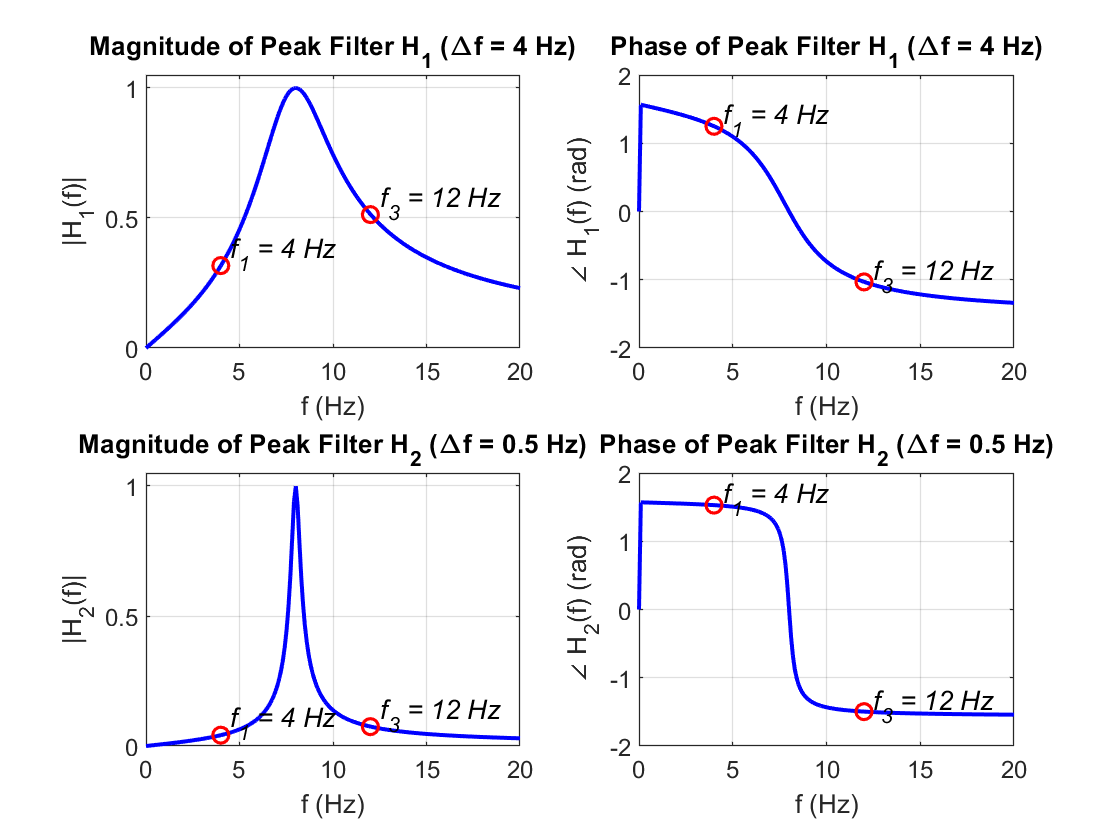


% Part 8.6 – Frequency-Response Plots for Peak Filters H1 & H2

fs = 400;            % Sampling frequency
N = 2048;            % Number of frequency points
f = linspace(0, fs/2, N);  % Frequency axis [Hz]

% Peak filter H1 (Δf = 4 Hz)
b1 = 0.030469 * [1 0 -1];
a1 = [1 -1.923772 0.939063];
[H1, ~] = freqz(b1, a1, N, fs);

% Peak filter H2 (Δf = 0.5 Hz)
b2 = 0.003912 * [1 0 -1];
a2 = [1 -1.976468 0.992177];
[H2, ~] = freqz(b2, a2, N, fs);

% Frequencies to mark
f1 = 4;   f3 = 12;
[~, i1] = min(abs(f - f1));
[~, i3] = min(abs(f - f3));

% Create 2×2 figure
figure("Name","Frequency-Response Plots for Peak Filters H1 & H2");

% ---- H1 Magnitude ----
subplot(2,2,1);
plot(f, abs(H1), 'b', 'LineWidth', 1.5); hold on;
plot(f1, abs(H1(i1)), 'ro', 'LineWidth', 1.2);
plot(f3, abs(H1(i3)), 'ro', 'LineWidth', 1.2);
text(f1+0.5, abs(H1(i1))+0.05, '\itf_1 = 4 Hz',  'FontSize',10);
text(f3+0.5, abs(H1(i3))+0.05, '\itf_3 = 12 Hz', 'FontSize',10);
title('Magnitude of Peak Filter H_1 (\Deltaf = 4 Hz)');
xlabel('f (Hz)'); ylabel('|H_1(f)|');
xlim([0 20]); ylim([0 1.05]); grid on;

% ---- H1 Phase ----
subplot(2,2,2);
plot(f, unwrap(angle(H1)), 'b', 'LineWidth', 1.5); hold on;
plot(f1, unwrap(angle(H1(i1))), 'ro', 'LineWidth', 1.2);
plot(f3, unwrap(angle(H1(i3))), 'ro', 'LineWidth', 1.2);
text(f1+0.5, unwrap(angle(H1(i1)))+0.1, '\itf_1 = 4 Hz',  'FontSize',10);
text(f3+0.5, unwrap(angle(H1(i3)))+0.1, '\itf_3 = 12 Hz', 'FontSize',10);
title('Phase of Peak Filter H_1 (\Deltaf = 4 Hz)');
xlabel('f (Hz)'); ylabel('\angle H_1(f) (rad)');
xlim([0 20]); ylim([-2 2]); grid on;

% ---- H2 Magnitude ----
subplot(2,2,3);
plot(f, abs(H2), 'b', 'LineWidth', 1.5); hold on;
plot(f1, abs(H2(i1)), 'ro', 'LineWidth', 1.2);
plot(f3, abs(H2(i3)), 'ro', 'LineWidth', 1.2);
text(f1+0.5, abs(H2(i1))+0.05, '\itf_1 = 4 Hz',  'FontSize',10);
text(f3+0.5, abs(H2(i3))+0.05, '\itf_3 = 12 Hz', 'FontSize',10);
title('Magnitude of Peak Filter H_2 (\Deltaf = 0.5 Hz)');
xlabel('f (Hz)'); ylabel('|H_2(f)|');
xlim([0 20]); ylim([0 1.05]); grid on;

% ---- H2 Phase ----
subplot(2,2,4);
plot(f, unwrap(angle(H2)), 'b', 'LineWidth', 1.5); hold on;
plot(f1, unwrap(angle(H2(i1))), 'ro', 'LineWidth', 1.2);
plot(f3, unwrap(angle(H2(i3))), 'ro', 'LineWidth', 1.2);
text(f1+0.5, unwrap(angle(H2(i1)))+0.1, '\itf_1 = 4 Hz',  'FontSize',10);
text(f3+0.5, unwrap(angle(H2(i3)))+0.1, '\itf_3 = 12 Hz', 'FontSize',10);
title('Phase of Peak Filter H_2 (\Deltaf = 0.5 Hz)');
xlabel('f (Hz)'); ylabel('\angle H_2(f) (rad)');
xlim([0 20]); ylim([-2 2]); grid on;

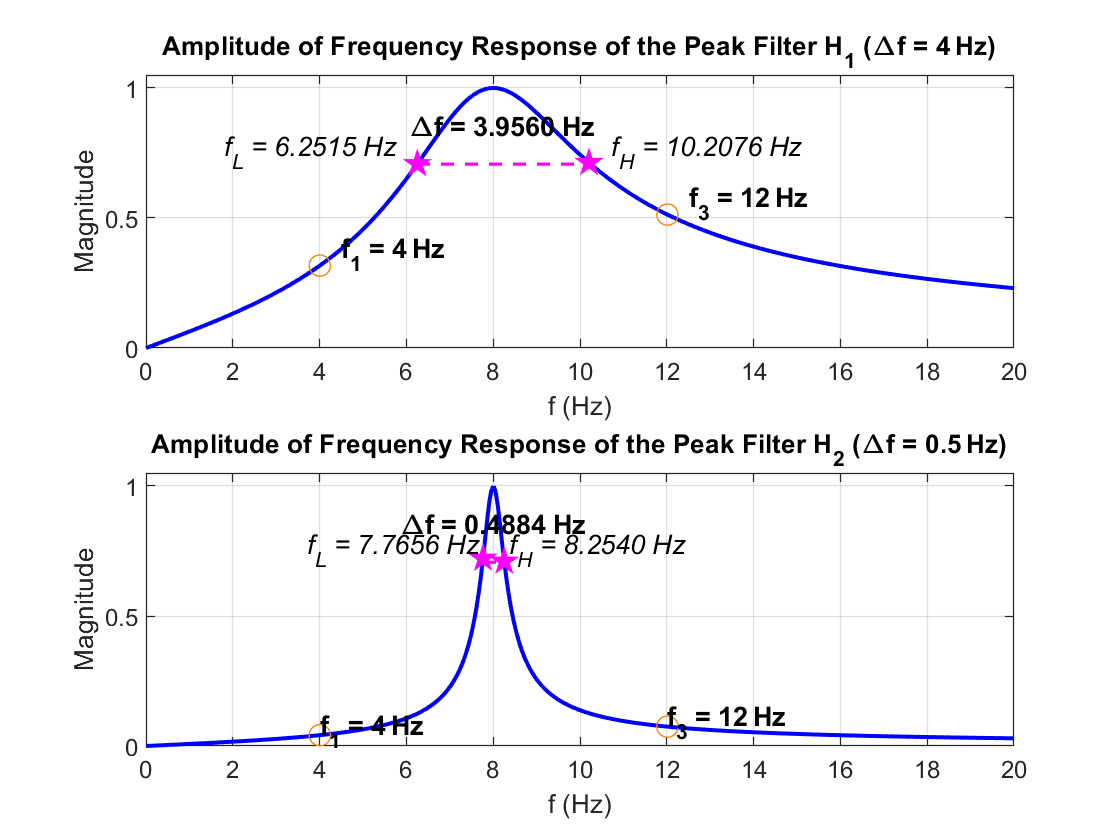

% Part 8.7 – 3 dB Bandwidth Annotations for Peak Filters

fs = 400;                
N  = 4096;               
f  = linspace(0, fs/2, N);

%% H1 (Δf = 4 Hz)
b1 = 0.030469*[1 0 -1];
a1 = [1 -1.923772 0.939063];
H1 = freqz(b1, a1, N, fs);
mag1 = abs(H1);

% find peak and –3 dB threshold
[~, ipk1] = max(mag1);
thr1 = mag1(ipk1)/sqrt(2);

% indices where mag ≥ thr
mask1 = mag1 >= thr1;
iL1 = find(mask1, 1, 'first');
iH1 = find(mask1, 1, 'last');

fL1 = f(iL1);
fH1 = f(iH1);

% find f1 and f3 positions
[~, i1] = min(abs(f-4));
[~, i3] = min(abs(f-12));

% Plot H1
figure("Name","3 dB Bandwidth Annotations for Peak Filters");
subplot(2,1,1);
plot(f, mag1, 'b', 'LineWidth',1.5); hold on;

% –3 dB line and markers
plot([fL1 fH1],[thr1 thr1], 'm--', 'LineWidth',1.2);
plot(f([iL1 iH1]), mag1([iL1 iH1]), 'mp','MarkerFaceColor','m','MarkerSize',10);

% f1 & f3 circles
plot(f(i1), mag1(i1), 'o','MarkerEdgeColor',[1 .5 0],'MarkerFaceColor','none','MarkerSize',8);
plot(f(i3), mag1(i3), 'o','MarkerEdgeColor',[1 .5 0],'MarkerFaceColor','none','MarkerSize',8);

% Annotations
text(f1+0.5, mag1(i1)+0.05, '\bff_{1} = 4 Hz');
text(f3+0.5, mag1(i3)+0.05, '\bff_{3} = 12 Hz');
text(fL1-0.5, thr1+0.05, sprintf('\\itf_L = %.4f Hz', fL1), 'HorizontalAlignment','right');
text(fH1+0.5, thr1+0.05, sprintf('\\itf_H = %.4f Hz', fH1));
text((fL1+fH1)/2, thr1+0.15, sprintf('\\Deltaf = %.4f Hz', fH1-fL1), ...
     'FontWeight','bold','HorizontalAlignment','center');

title('Amplitude of Frequency Response of the Peak Filter H_1 (\Deltaf = 4 Hz)');
xlabel('f (Hz)'); ylabel('Magnitude');
xlim([0 20]); ylim([0 1.05]);
grid on;


%% H2 (Δf = 0.5 Hz)
b2 = 0.003912*[1 0 -1];
a2 = [1 -1.976468 0.992177];
H2 = freqz(b2, a2, N, fs);
mag2 = abs(H2);

% –3 dB threshold
[~, ipk2] = max(mag2);
thr2 = mag2(ipk2)/sqrt(2);
mask2 = mag2 >= thr2;
iL2 = find(mask2, 1, 'first');
iH2 = find(mask2, 1, 'last');
fL2 = f(iL2);
fH2 = f(iH2);

% f1 and f3 again
[~, i1b] = min(abs(f-4));
[~, i3b] = min(abs(f-12));

% Plot H2
subplot(2,1,2);
plot(f, mag2, 'b', 'LineWidth',1.5); hold on;

plot([fL2 fH2],[thr2 thr2], 'm--', 'LineWidth',1.2);
plot(f([iL2 iH2]), mag2([iL2 iH2]), 'mp','MarkerFaceColor','m','MarkerSize',10);

plot(f(i1b), mag2(i1b), 'o','MarkerEdgeColor',[1 .5 0],'MarkerFaceColor','none','MarkerSize',8);
plot(f(i3b), mag2(i3b), 'o','MarkerEdgeColor',[1 .5 0],'MarkerFaceColor','none','MarkerSize',8);

text(4, mag2(i1b)+0.02, '\bff_{1} = 4 Hz');
text(12, mag2(i3b)+0.02, '\bff_{3} = 12 Hz');
text(fL2-0.1, thr2+0.05, sprintf('\\itf_L = %.4f Hz', fL2), 'HorizontalAlignment','right');
text(fH2+0.1, thr2+0.05, sprintf('\\itf_H = %.4f Hz', fH2));
text((fL2+fH2)/2, thr2+0.15, sprintf('\\Deltaf = %.4f Hz', fH2-fL2), ...
     'FontWeight','bold','HorizontalAlignment','center');

title('Amplitude of Frequency Response of the Peak Filter H_2 (\Deltaf = 0.5 Hz)');
xlabel('f (Hz)'); ylabel('Magnitude');
xlim([0 20]); ylim([0 1.05]);
grid on;